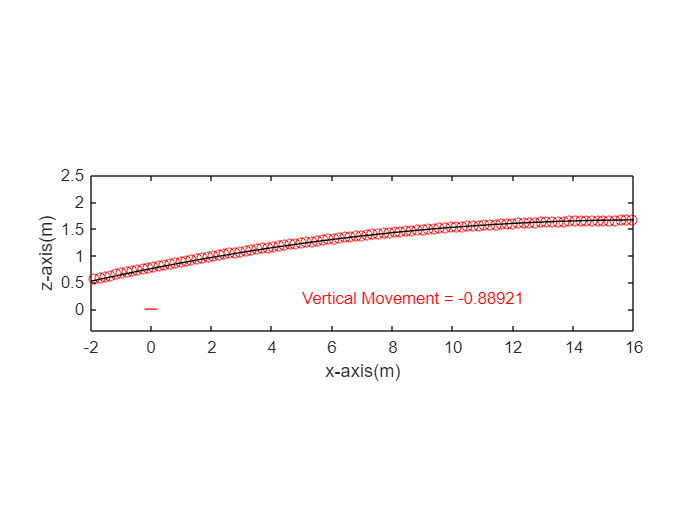

clear all;

%initial condition

rho = 1.225; %空氣密度
A = pi*0.037^2; %球截面積
m = 0.1455; %棒球質量
V = 38.132; %球速純量
Omega = 260.961; %轉速純量
C = rho*A*V/(2*m);

CL = 0.15;
CD = 0.2;
CY = 0.005;

x = [16.332, 0.76, 1.67]; %位置
xf = [16.332, 0.76, 1.67]; %free fall
r = [0, 0, 1.67]; %5號位
v = V.*(r-x)./((r - x)*(r - x).')^0.5; %速度
vf = V.*(r-x)./((r - x)*(r - x).')^0.5; %free fall
a = [0, 0, 0]; %加速度
af = [0, 0, 0]; %free fall
l = [-50, 8.3, 41.7]; %轉軸
omega = Omega.*l./(l*l.')^0.5; %角速度
g = [0, 0, -9.8]; %重力加速度

t = 300;
dt = 0.005;

%loop

while t>0
    a(end+1, 1) = C*((CL/Omega)*(v(end, 3)*omega(end, 2) - omega(end, 3)*v(end, 2)) - CD*v(end, 1) + (CY/(Omega*V))*(v(end, 2)^2*omega(end, 1) - v(end, 1)*v(end, 2)*omega(end, 2) - v(end, 1)*v(end, 3)*omega(end, 3) + v(end, 3)^2*omega(end, 1)));
    a(end, 2) = C*((CL/Omega)*(v(end, 1)*omega(end, 3) - omega(end, 1)*v(end, 3)) - CD*v(end, 2) + (CY/(Omega*V))*(v(end, 3)^2*omega(end, 2) - v(end, 2)*v(end, 3)*omega(end, 3) - v(end, 2)*v(end, 1)*omega(end, 1) + v(end, 1)^2*omega(end, 2)));
    a(end, 3) = C*((CL/Omega)*(v(end, 2)*omega(end, 1) - omega(end, 2)*v(end, 1)) - CD*v(end, 3) + (CY/(Omega*V))*(v(end, 1)^2*omega(end, 3) - v(end, 3)*v(end, 1)*omega(end, 1) - v(end, 3)*v(end, 2)*omega(end, 2) + v(end, 2)^2*omega(end, 3))) + g(3);

    af(end+1, 1) = 0;
    af(end, 2) = 0;
    af(end, 3) = g(3);

    v(end+1, 1) = v(end, 1) + a(end, 1)*dt;
    v(end, 2) = v(end-1, 2) + a(end, 2)*dt;
    v(end, 3) = v(end-1, 3) + a(end, 3)*dt;

    vf(end+1, 1) = vf(end, 1) + af(end, 1)*dt;
    vf(end, 2) = vf(end-1, 2) + af(end, 2)*dt;
    vf(end, 3) = vf(end-1, 3) + af(end, 3)*dt;

    x(end+1, 1) = x(end, 1) + v(end, 1)*dt;
    x(end, 2) = x(end-1, 2) + v(end, 2)*dt;
    x(end, 3) = x(end-1, 3) + v(end, 3)*dt;

    xf(end+1, 1) = xf(end, 1) + vf(end, 1)*dt;
    xf(end, 2) = xf(end-1, 2) + vf(end, 2)*dt;
    xf(end, 3) = xf(end-1, 3) + vf(end, 3)*dt;

    t = t - 1;
end

%homebase

hx = [0.2159, 0.2159, 0, -0.2152, 0, 0.2159];
hy = [0.2159, -0.2159, -0.2159, 0, 0.2159, 0.2159];

%movement

i = 1;
while(x(i, 1) >= 0)
    i = i + 1;
end

%plot

plot(x(:, 1), x(:, 3), 'o', Color='red');
hold on;
plot(xf(:, 1), xf(:, 3), Color='black');
plot([-0.2152, 0.2159], [0, 0], Color='red');
hold off;
pbaspect([3.5 1 1]);
xlabel('x-axis(m)');
ylabel('z-axis(m)');
xlim([-2, 16]);
ylim([-0.4, 2.5]);
txt = ['Vertical Movement = ', num2str(x(i, 3) - xf(1, 3))];
text(5, 0.2, txt, 'FontSize', 10, 'Color', 'r');

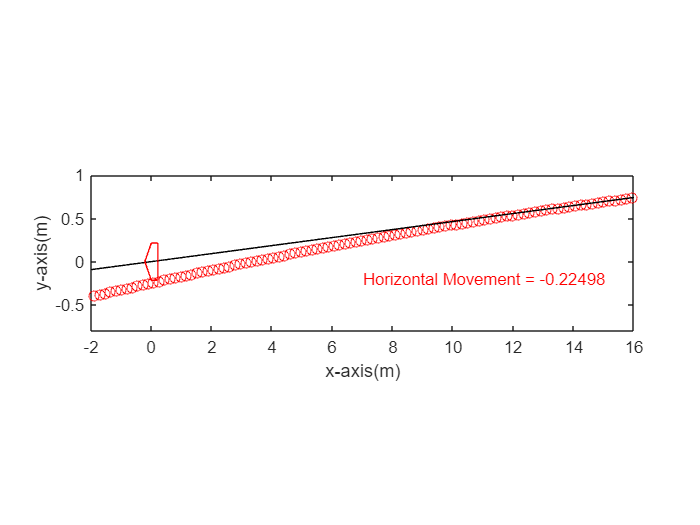

plot(x(:, 1), x(:, 2), 'o', Color='red');
hold on;
plot(xf(:, 1), xf(:, 2), Color='black');
plot(hx, hy, Color='red');
hold off;
pbaspect([3.5 1 1]);
xlabel('x-axis(m)');
ylabel('y-axis(m)');
xlim([-2, 16]);
ylim([-0.8, 1]);
txt = ['Horizontal Movement = ', num2str(x(i, 2) - xf(i, 2))];
text(7, -0.2, txt, 'FontSize', 10, 'Color', 'r');